% =========================================================
% controlador_pid.m
% Grupo G1 - Controle de Altitude de Drone
% UTFPR Apucarana - Analise de Sistemas Lineares 2026-1
% =========================================================
% Planta: G(s) = (1/m) / [s*(s + b/m)]
% Controlador: PID com filtro derivativo
%   C(s) = Kp + Ki/s + Kd*N*s/(s+N)
%   O filtro N torna C(s) proprio (realizavel fisicamente).
%   PID puro (Kd*s) e improprio e nao pode ser simulado com lsim.
% Sinal de controle u(t) obtido por lsim(C_pid, e, t)
%   onde e(t) = r(t) - y(t)  (erro de rastreamento)
% =========================================================

clear; clc; close all;

%% --- Parametros nominais do sistema ---
m = 1.2;        % massa [kg]
b = 0.5;        % coeficiente de amortecimento [N.s/m]
t  = (0:0.01:30)';   % vetor de tempo [s]
r  = ones(size(t));  % referencia degrau unitario (1 metro de altitude)

%% --- Funcao de transferencia da planta ---
num_G = [1/m];
den_G = [1, b/m, 0];
G = tf(num_G, den_G);

fprintf('=== Planta G(s) ===\n');

=== Planta G(s) ===


G

G =
 
      0.8333
  --------------
  s^2 + 0.4167 s
 
Continuous-time transfer function.
Model Properties



%% --- Sintonia automatica com pidtune ---
% Usar 'PIDF' (PID com filtro derivativo) em vez de 'PID'.
% PID puro tem termo Kd*s (improprio) que lsim nao consegue simular.
% PIDF: C(s) = Kp + Ki/s + Kd*N*s/(s+N)  -> proprio e realizavel.
% N e o coeficiente do filtro (aqui controlado pelo Tf = 1/N do pid()).
C_pid_auto = pidtune(G, 'PIDF');
fprintf('=== Ganhos iniciais via pidtune (PIDF) ===\n');

=== Ganhos iniciais via pidtune (PIDF) ===


fprintf('  Kp = %.4f\n', C_pid_auto.Kp);

  Kp = 0.4350


fprintf('  Ki = %.4f\n', C_pid_auto.Ki);

  Ki = 0.0421


fprintf('  Kd = %.4f\n', C_pid_auto.Kd);

  Kd = 0.7834


fprintf('  Tf = %.4f  (filtro derivativo: N = 1/Tf = %.4f)\n', C_pid_auto.Tf, 1/C_pid_auto.Tf);

  Tf = 0.3695  (filtro derivativo: N = 1/Tf = 2.7063)



%% --- Ajuste manual dos ganhos ---
% pidtune e ponto de partida. Ajuste manual para melhorar:
%   - Overshoot  (reduzir Kp ou aumentar Kd)
%   - Tempo de assentamento  (aumentar Ki)
%   - Oscilacoes  (aumentar Kd com cuidado)
%
% Valores ajustados manualmente apos analise da resposta:
Kp = C_pid_auto.Kp;
Ki = C_pid_auto.Ki;
Kd = C_pid_auto.Kd;
Tf = C_pid_auto.Tf;   % filtro derivativo: N = 1/Tf
% INSTRUCAO: se a resposta oscilar muito, aumente Kd ou reduza Tf.
%            se o erro em regime permanente for nao-nulo, aumente Ki.
%            ajuste e re-rode o script para ver o efeito.

C_pid = pid(Kp, Ki, Kd, Tf);
fprintf('\n=== Ganhos PID utilizados ===\n');


=== Ganhos PID utilizados ===


fprintf('  Kp = %.4f\n', Kp);

  Kp = 0.4350


fprintf('  Ki = %.4f\n', Ki);

  Ki = 0.0421


fprintf('  Kd = %.4f\n', Kd);

  Kd = 0.7834


fprintf('  Tf = %.4f  (N = %.4f)\n', Tf, 1/Tf);

  Tf = 0.3695  (N = 2.7063)



%% --- Malha fechada ---
% T(s) = C(s)*G(s) / (1 + C(s)*G(s))
T_pid = feedback(C_pid * G, 1);

fprintf('\n=== Polos da malha fechada (PID) ===\n');


=== Polos da malha fechada (PID) ===


p_mf = pole(T_pid);
for i = 1:length(p_mf)
    fprintf('  p%d = %.4f + %.4fi\n', i, real(p_mf(i)), imag(p_mf(i)));
end

  p1 = -1.3426 + 0.4818i
  p2 = -1.3426 + -0.4818i
  p3 = -0.2537 + 0.0000i
  p4 = -0.1841 + 0.0000i


if all(real(p_mf) < 0)
    fprintf('Sistema em malha fechada: ESTAVEL (todos os polos com parte real negativa)\n');
else
    fprintf('ATENCAO: sistema instavel! Ajustar ganhos.\n');
end

Sistema em malha fechada: ESTAVEL (todos os polos com parte real negativa)



%% --- Simulacao da saida y(t) ---
y = lsim(T_pid, r, t);

%% --- Sinal de controle u(t) correto ---
% u(t) e a saida do controlador C(s) quando alimentado pelo erro e(t).
% e(t) = r(t) - y(t)
% u(t) = lsim(C_pid, e, t)
%
% Isso e correto porque em malha fechada:
%   E(s) = R(s) - Y(s)
%   U(s) = C(s) * E(s)
% Portanto simular C(s) com entrada e(t) fornece o sinal de controle real.
e = r - y;
u = lsim(C_pid, e, t);

%% --- Metricas de desempenho ---
% RMSE: raiz do erro quadratico medio
RMSE = sqrt(mean(e.^2));

% ISE: integral do erro ao quadrado  int(e^2 dt)
ISE  = trapz(t, e.^2);

% IAE: integral do valor absoluto do erro  int(|e| dt)
IAE  = trapz(t, abs(e));

% ITAE: integral do tempo pelo valor absoluto do erro  int(t*|e| dt)
% penaliza erros que persistem por mais tempo
ITAE = trapz(t, t .* abs(e));

fprintf('\n=== Metricas de Desempenho - PID ===\n');


=== Metricas de Desempenho - PID ===


fprintf('  RMSE = %.6f\n', RMSE);

  RMSE = 0.170914


fprintf('  ISE  = %.6f\n', ISE);

  ISE  = 0.871638


fprintf('  IAE  = %.6f\n', IAE);

  IAE  = 2.307574


fprintf('  ITAE = %.6f\n', ITAE);

  ITAE = 12.954508


fprintf('Copiar esses valores para o Kauan montar a tabela comparativa.\n');

Copiar esses valores para o Kauan montar a tabela comparativa.



%% --- Informacoes de desempenho temporal ---
info = stepinfo(T_pid);
fprintf('\n=== Informacoes de resposta ao degrau ===\n');


=== Informacoes de resposta ao degrau ===


fprintf('  Tempo de subida  (10-90%%): %.4f s\n', info.RiseTime);

  Tempo de subida  (10-90%): 1.7726 s


fprintf('  Tempo de pico:             %.4f s\n', info.PeakTime);

  Tempo de pico:             5.4881 s


fprintf('  Overshoot:                 %.4f %%\n', info.Overshoot);

  Overshoot:                 10.3165 %


fprintf('  Tempo de assentamento:     %.4f s\n', info.SettlingTime);

  Tempo de assentamento:     19.4710 s


% info.SteadyStateValue pode nao existir em versoes antigas do MATLAB
% usar dcgain(T_pid) que e equivalente e sempre funciona
fprintf('  Valor em regime permanente: %.4f\n', dcgain(T_pid));

  Valor em regime permanente: 1.0000


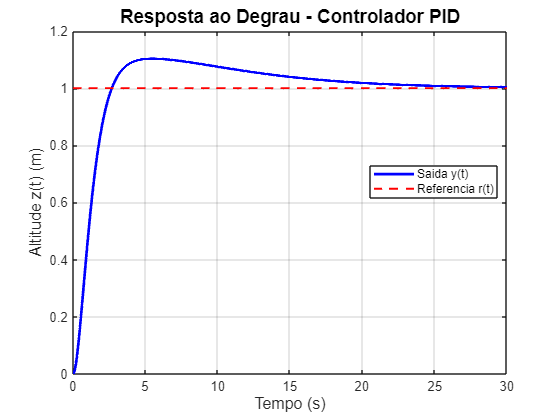


%% --- Figura 1: Resposta ao degrau com referencia ---
figure(1);
plot(t, y, 'b-', 'LineWidth', 2); hold on;
plot(t, r, 'r--', 'LineWidth', 1.5);
hold off;
title('Resposta ao Degrau - Controlador PID', 'FontSize', 14);
xlabel('Tempo (s)', 'FontSize', 12);
ylabel('Altitude z(t) (m)', 'FontSize', 12);
legend('Saida y(t)', 'Referencia r(t)', 'Location', 'best');
grid on;

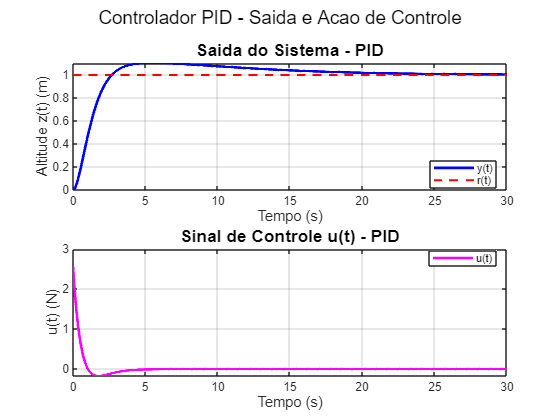


%% --- Figura 2: Subplot saida + sinal de controle u(t) ---
figure(2);
subplot(2,1,1);
plot(t, y, 'b-', 'LineWidth', 2); hold on;
plot(t, r, 'r--', 'LineWidth', 1.5);
hold off;
title('Saida do Sistema - PID', 'FontSize', 13);
xlabel('Tempo (s)', 'FontSize', 11);
ylabel('Altitude z(t) (m)', 'FontSize', 11);
legend('y(t)', 'r(t)', 'Location', 'best');
grid on;

subplot(2,1,2);
plot(t, u, 'm-', 'LineWidth', 2);
title('Sinal de Controle u(t) - PID', 'FontSize', 13);
xlabel('Tempo (s)', 'FontSize', 11);
ylabel('u(t) (N)', 'FontSize', 11);
legend('u(t)', 'Location', 'best');
grid on;

sgtitle('Controlador PID - Saida e Acao de Controle', 'FontSize', 14);


fprintf('\n=== Script controlador_pid.m executado com sucesso ===\n');


=== Script controlador_pid.m executado com sucesso ===


fprintf('Salvar figuras:\n');

Salvar figuras:


fprintf('  fig_pid_resposta.png   (Figura 1)\n');

  fig_pid_resposta.png   (Figura 1)


fprintf('  fig_pid_subplot.png    (Figura 2)\n');

  fig_pid_subplot.png    (Figura 2)



%% --- Exportar variaveis para uso no espectrograma (Arthur S3) ---
% Salvar u_pid e t para uso no script do espectrograma
save('dados_pid.mat', 'u', 't', 'y', 'e', 'Kp', 'Ki', 'Kd', 'Tf', 'RMSE', 'ISE', 'IAE', 'ITAE');
fprintf('Variaveis salvas em dados_pid.mat para uso no espectrograma (S3).\n');

Variaveis salvas em dados_pid.mat para uso no espectrograma (S3).
